clear all;
chart = readtable("chr_A_wzm_o_G_1_Rosa.xls")

chart = 21×5 table
    Cz_stotliwo__Wej_cia_kHz_    AmplitudaWej_cia_V_    AmplitudaWyj_cia_V_    G_Vin_Vout_     G_dB_  
    _________________________    ___________________    ___________________    ___________    ________

               100                      1.03                   1.04              1.0097       0.083922
               126                      1.03                   1.04              1.0097       0.083922
               158                      1.03                   1.04              1.0097       0.083922
               199                      1.03                   1.05              1.0194        0.16704
               251                      1.03                   1.04              1.0097       0.083922
               316                      1.03                   1.05              1.0194  

charm = table2array(chart);

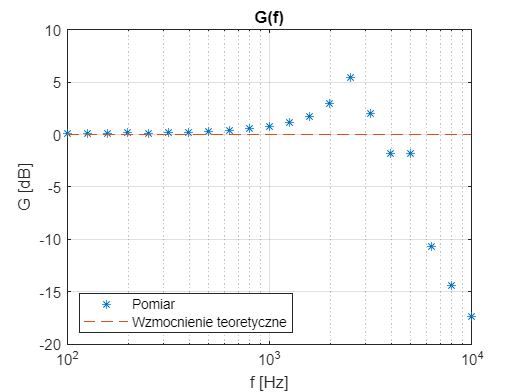

figure()
g_teor = zeros(size(charm(:,1)));
semilogx(charm(:,1), charm(:,5), "*", charm(:,1), g_teor, "--");
title("G(f)")
xlabel("f [Hz]")
ylabel("G [dB]")
legend(["Pomiar", "Wzmocnienie teoretyczne"], 'Location','southwest')
grid on;

clear all;
chart = readtable("chr_A_i_F_wzm_niodwrac_Rosa.xls")

chart = 25×6 table
    Cz_stotliwo__Wej_cia_kHz_    AmplitudaWej_cia_V_    AmplitudaWyj_cia_V_    Przesuni_cieFazowe_stopnie_    G_V_out_V_in_     G_dB_ 
    _________________________    ___________________    ___________________    ___________________________    _____________    _______

               100                      1.04                    5.72                        12                      5.5         14.807
               126                      1.04                    5.72                        12                      5.5         14.807
               158                      1.04                     5.7                        15                   5.4808         14.777
               199                      1.04                    5.56                        21       

charm = table2array(chart(1:21, :));

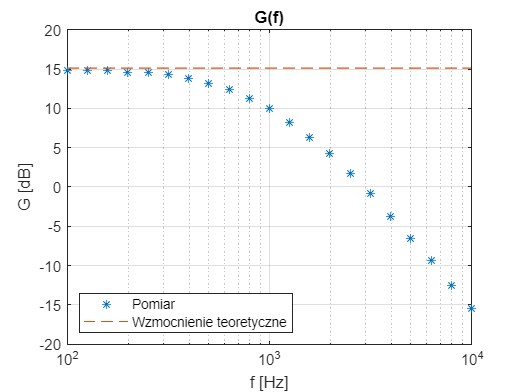

figure()
g_teor = 20*log10(5.7) * ones(size(charm(:,1)));
semilogx(charm(:,1), charm(:,6), "*", charm(:,1), g_teor, "--");
title("G(f)")
xlabel("f [Hz]")
ylabel("G [dB]")
legend(["Pomiar", "Wzmocnienie teoretyczne"], 'Location','southwest')
grid on;

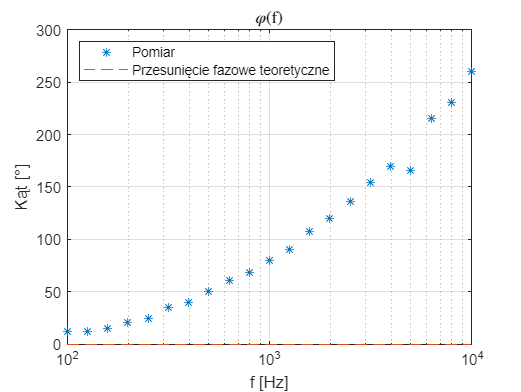

figure()
g_teor = zeros(size(charm(:,1)));
semilogx(charm(:,1), charm(:,4), "*", charm(:,1), g_teor, "--");
title({'$\varphi$(f)'},'Interpreter','latex')
xlabel("f [Hz]")
ylabel("Kąt [" + char(176) + "]")
legend(["Pomiar", "Przesunięcie fazowe teoretyczne"], 'Location','northwest')
grid on;

clear all;
chart = readtable("chr_A_i_F_wzm_odwrac_Rosa.xls")

chart = 21×6 table
    Cz_stotliwo__Wej_cia_kHz_    AmplitudaWej_cia_V_    AmplitudaWyj_cia_V_    Przesuni_cieFazowe_stopnie_    G_V_in_V_out_     G_dB_  
    _________________________    ___________________    ___________________    ___________________________    _____________    ________

               100                      0.976                  -2.12                      -172                   -2.1721         6.7377
               126                      0.976                  -2.14                      -171                   -2.1926         6.8193
               158                      0.976                  -2.14                      -169                   -2.1926         6.8193
               199                      0.976                  -2.13                      -169  

charm = table2array(chart(1:21, :));

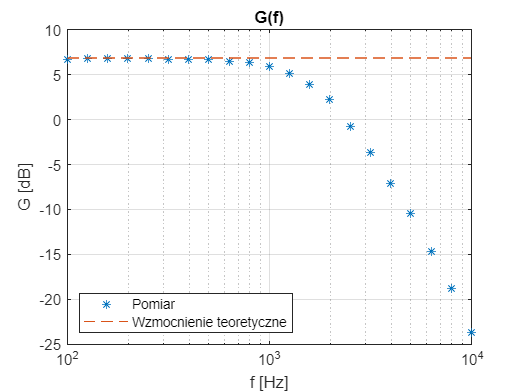

figure()
g_teor = 20*log10(2.2) * ones(size(charm(:,1)));
semilogx(charm(:,1), charm(:,6), "*", charm(:,1), g_teor, "--");
title("G(f)")
xlabel("f [Hz]")
ylabel("G [dB]")
legend(["Pomiar", "Wzmocnienie teoretyczne"], 'Location','southwest')
grid on;

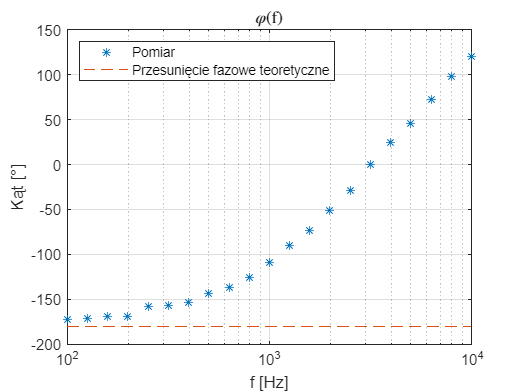

figure()
g_teor = -180 * ones(size(charm(:,1)));
semilogx(charm(:,1), charm(:,4), "*", charm(:,1), g_teor, "--");
title({'$\varphi$(f)'},'Interpreter','latex')
xlabel("f [Hz]")
ylabel("Kąt [" + char(176) + "]")
legend(["Pomiar", "Przesunięcie fazowe teoretyczne"], 'Location','northwest')
grid on;

clear all;
chart = readtable("chr_przejsc_wzm_odwrac_Rosa.xls")

chart = 25×3 table
    Napi_cieNaWej_ciu_V_    NapiecieNaWyjsciu_V_    Progi_V_
    ____________________    ____________________    ________

              -6                     NaN               NaN  
            -5.5                     8.4               NaN  
              -5                     8.4               NaN  
            -4.5                     8.4               NaN  
              -4                     8.4              -3.8  
            -3.5                     7.8               NaN  
              -3                     6.6               NaN  
            -2.5                     5.6               NaN  
              -2                     4.4               NaN  
            -1.5                     3.2               NaN  
              -1                       2               NaN  
            -0.5                       1               NaN  
               0        

charm = table2array(chart);

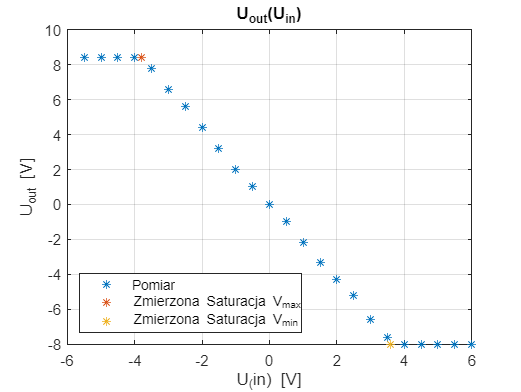

figure()
saturacja_min = charm(5, 3);
saturacja_max = charm(20, 3);
plot(charm(:,1), charm(:,2), "*",...
    saturacja_min ,max(charm(:, 2)), "*",...
    saturacja_max ,min(charm(:, 2)), "*");
title('U_{out}(U_{in})', 'Interpreter', 'tex')
xlabel('U_(in) [V]', 'Interpreter', 'tex')
ylabel('U_{out} [V]', 'Interpreter', 'tex')
legend(["Pomiar", "Zmierzona Saturacja V_{max}", "Zmierzona Saturacja V_{min}"], 'Location','southwest','Interpreter','tex')
grid on;